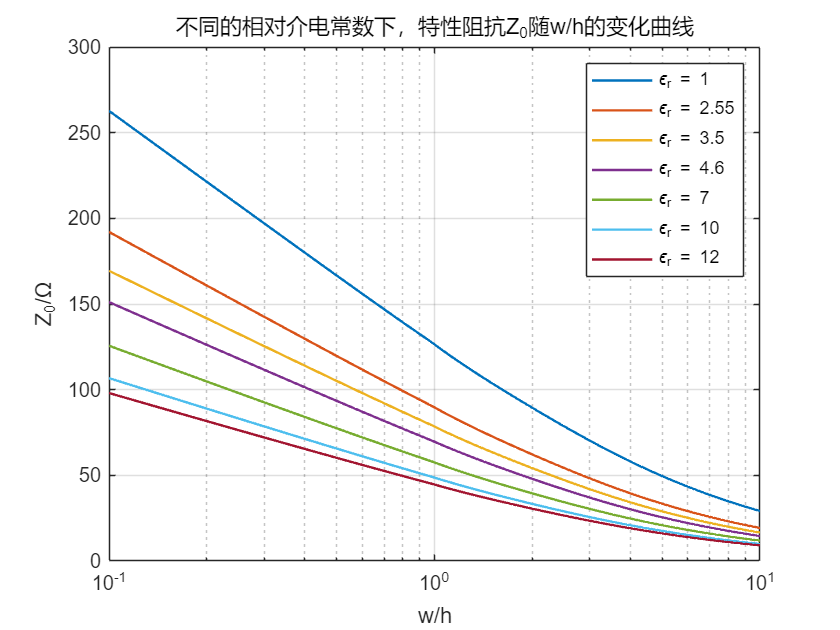

000%----实验内容1----%
clc;
clear;
wh_step=0.01;
wh=0.1:wh_step:10;
eps_relative=[1,2.55,3.5,4.6,7,10,12];
h=0.001;
Z0=zeros(length(eps_relative),length(wh));
eps_effective=zeros(length(eps_relative),length(wh));
for i=1:length(eps_relative)
    [Z0(i,:),eps_effective(i,:)]=Z0_microstrip(wh,eps_relative(i),0,h);
end
figure(1);
semilogx(wh, Z0, 'LineWidth', 1.2);
legend('\epsilon_r = 1', '\epsilon_r = 2.55', '\epsilon_r = 3.5', ...
    '\epsilon_r = 4.6', '\epsilon_r = 7', '\epsilon_r = 10', '\epsilon_r = 12');
xlabel('w/h');
ylabel('Z_0/\Omega');
title('不同的相对介电常数下，特性阻抗Z_0随w/h的变化曲线');
grid on;

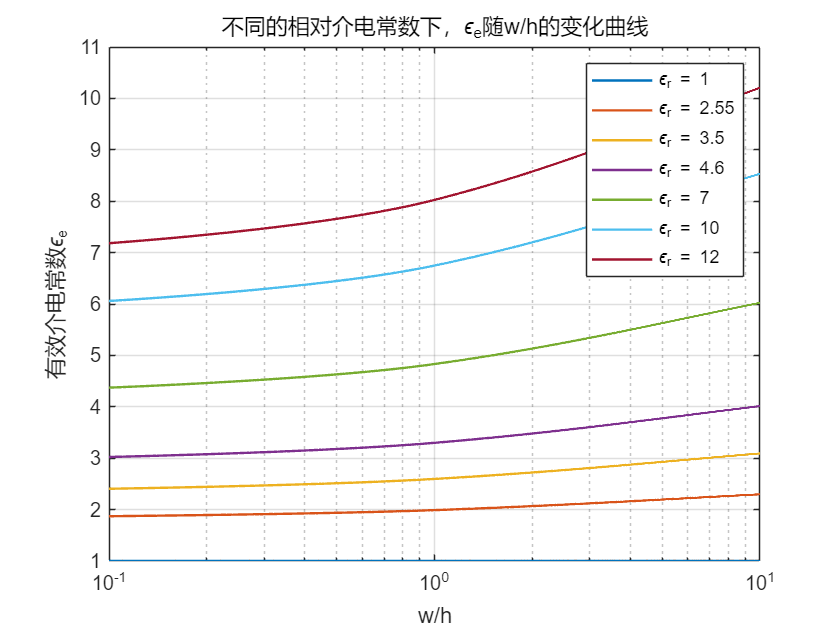


figure(2);
semilogx(wh,eps_effective,'LineWidth',1.2);
legend('\epsilon_r = 1', '\epsilon_r = 2.55', '\epsilon_r = 3.5', ...
    '\epsilon_r = 4.6', '\epsilon_r = 7', '\epsilon_r = 10', '\epsilon_r = 12');
xlabel('w/h');
ylabel('有效介电常数\epsilon_e');
title('不同的相对介电常数下，\epsilon_e随w/h的变化曲线');
grid on;

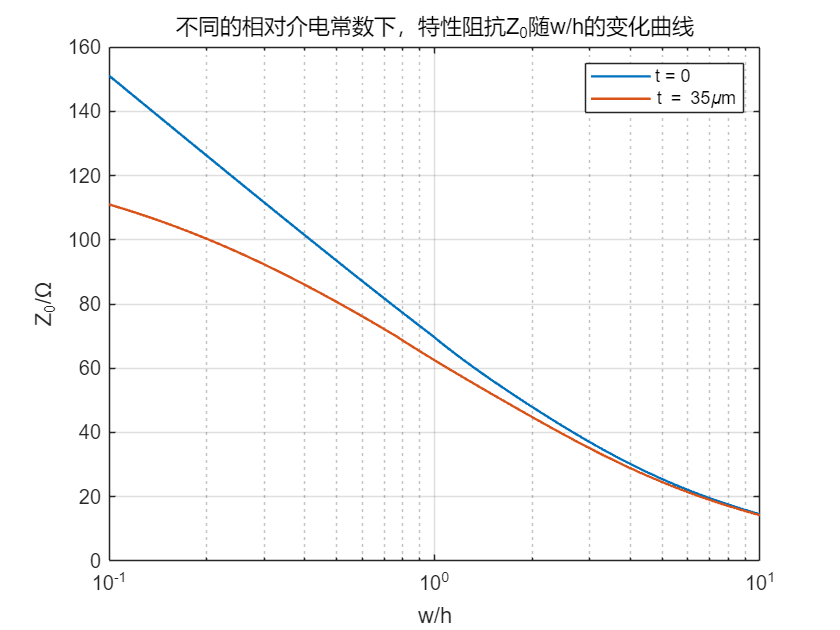


%----实验内容2----%

[Z0_fr4(1,:),eps_effective_fr4(1,:)]=Z0_microstrip(wh,4.6,0,h);
[Z0_fr4(2,:),eps_effective_fr4(2,:)]=Z0_microstrip(wh,4.6,35e-6,h);
figure(3);
semilogx(wh,Z0_fr4,'LineWidth',1.2);
legend('t = 0', 't = 35\mum');
xlabel('w/h');
ylabel('Z_0/\Omega');
title('不同的相对介电常数下，特性阻抗Z_0随w/h的变化曲线');
grid on;


%----实验内容3----%
h2=1;           %1mm
t_3=0;
c=3e8;
f=1e9;
Z0_3=[50,100];
eps_relative3=4.6;
wh_fr4=whcal_mstrip(Z0_3,eps_relative3);
w=h2*wh_fr4;
[Z0_3,eps_effective3]=Z0_microstrip(wh_fr4,eps_relative3,t_3,h2);
L=1/4*c/f./sqrt(eps_effective3)*1000;  %mm

%-----微带线特性阻抗-----%
function [Z0,eps_effective]=Z0_microstrip(wh,er,t,h)
    if t~=0
        if wh>1/(2*pi)
            whs=wh+t/(pi*h)*(1+log(2*h/t));
        else
            whs=wh+t/(pi*h)*(1+log(4*pi*wh/(t*h)));
        end
%whs=(wh+t/(pi*h)*(1+log(2*h/t))).*(wh>=1/(2*pi))+(wh+t/(pi*h)*(1+log(4*pi*wh/(t*h)))).*(wh<=1/(2*pi));
        wh=whs;
    end
    Z0a=59.952.*log(8./wh+wh/4).*(wh<=1)+119.904.*pi./(wh+2.42-0.44./wh+(1-1./wh).^6).*(wh>1);
    q=(0.5+0.5*((1+12./wh).^(-0.5)+0.041.*(1-wh).^2)).*(wh<=1)+(wh>1).*(0.5+0.5.*(1+12./wh).^-0.5);
    eps_effective=ones(1,length(q))+q.*(er-1);
    Z0=Z0a./sqrt(eps_effective);
end

function wh=whcal_mstrip(Z0,eps_relative)
    if Z0>44-2*eps_relative
        A=Z0.*sqrt(2*(eps_relative+1))/119.9+(eps_relative-1)/(2.*(eps_relative+1))*(log(pi/2)+1/eps_relative*log(4/pi));
        wh=1./(exp(A)/8-1./(4*exp(A)));
    else
        B=59.95*pi^2/(Z0.*sqrt(eps_relative));
        wh=2/pi*((B-1)-log(2*B-1))+(eps_relative-1)/pi/eps_relative.*(log(B-1)+0.293-0.517./eps_relative);
    end
end